%cd('/Users/yarinms/marvin/LAST.01.05.01/2024/08/11/proc')
cd('/Volumes/Extreme SSD/YS_data/LAST.01.05.01/2024/08/11/proc')
List = MatchedSources.rdirMatchedSourcesSearch('FileTemplate','*.hdf5');

FN = 'Test30s';
if exist("List","var")
    flag =1;
end


Args.MagField = {'MAG_PSF'}; Args.MagErrField = {'MAGERR_PSF'};
Args.BadFlags = {'Saturated','Negative','NaN' ,'Spike','Hole','CR_DeltaHT','NearEdge'};
Args.EdgeFlags = {'Overlap'};
Args.runMeanFilterArgs      = {'Threshold',5, 'StdFun','OutWin'};
Args.Nvisits = 1;
Args.Ndet = 14*Args.Nvisits;


list = List;

 mB17_175 =zeros(24,6);
 mB175_18 =zeros(24,6);
 mB18_185 =zeros(24,6);
 mB185_19 =zeros(24,6);
 mB19_195 =zeros(24,6);
 mB1195=zeros(24,6);
 FRD1=zeros(24,1);
 FRD2=zeros(24,1);
 FRD3=zeros(24,1);

  nB17_175 =zeros(24,6);
 nB175_18 =zeros(24,6);
 nB18_185 =zeros(24,6);
 nB185_19 =zeros(24,6);
 nB19_195 =zeros(24,6);
 nB1195=zeros(24,6);

 cm17_172 =zeros(24,6);
cm172_174 =zeros(24,6);
cm174_176 =zeros(24,6);
cm176_178 =zeros(24,6);
cm178_18 =zeros(24,6);
cm18_182 =zeros(24,6);
cm182_184 =zeros(24,6);
cm184_186 =zeros(24,6);
cm186_188 =zeros(24,6);
cm188_19 =zeros(24,6);
cm19_192 =zeros(24,6);
cm192_194 =zeros(24,6);
cm194_196 =zeros(24,6);

cn17_172 =zeros(24,6);
cn172_174 =zeros(24,6);
cn174_176 =zeros(24,6);
cn176_178 =zeros(24,6);
cn178_18=zeros(24,6);
cn18_182=zeros(24,6);
cn182_184=zeros(24,6);
cn184_186=zeros(24,6);
cn186_188=zeros(24,6);
cn188_19=zeros(24,6);
cn19_192=zeros(24,6);
cn192_194=zeros(24,6);
cn194_196=zeros(24,6);

Mex19 = [];
Mex18 = [];
Mex17 = [];

Fap =zeros(24,6);
allSrcStat = zeros(24,6);
allSrcN = zeros(24,6);
h = waitbar(0);
detEff = [];
mEff = [];
AllFap = [];
AllS = 0;
tic
for Iid = 1:24 



    list1.FileName = List(Iid).FileName(contains(List(Iid).FileName,FN));
    list1.Folder   = List(Iid).Folder(contains(List(Iid).FileName,FN));
    list1.CropID = List(Iid).CropID;
    ms1 =  MatchedSources.readList(list1);
    Nvis = length(ms1);


    for Ivis = 1: Nvis
    

        MMS = ms1(Ivis).setBadPhotToNan('BadFlags',Args.BadFlags, 'MagField','MAG_PSF', 'CreateNewObj',true);
        R = lcUtil.zp_meddiff(MMS,'MagField',Args.MagField,'MagErrField',Args.MagErrField);
        [MMS,ApplyToMagFieldr] = applyZP(MMS, R.FitZP,'ApplyToMagField',Args.MagField);
        % Remove sources with NdetGood<MinNdet
        NdetGood = sum(~isnan(MMS.Data.MAG_PSF), 1);

        Fndet    = NdetGood>Args.Ndet;

        % Fndet  = Fndet & (mean(MMS.Data.MAG_PSF,'omitnan') < 19.5);
        allSrc  = MMS.Nsrc;
        goodSrc = sum(Fndet);
        allSrcStat(Iid,Ivis) = goodSrc/allSrc;
        allSrcN(Iid,Ivis) = allSrc;

        % MagBinStat
        flag1 = mean(MMS.Data.MAG_PSF,'omitnan') > 17 & mean(MMS.Data.MAG_PSF,'omitnan') < 17.5;
        mB17_175(Iid,Ivis) = sum(Fndet & flag1)/sum(flag1);
        flag2 = mean(MMS.Data.MAG_PSF,'omitnan') > 17.5 & mean(MMS.Data.MAG_PSF,'omitnan') < 18;
        mB175_18(Iid,Ivis) = sum(Fndet & flag2)/sum(flag2);
        flag3 = mean(MMS.Data.MAG_PSF,'omitnan') > 18 & mean(MMS.Data.MAG_PSF,'omitnan') < 18.5;
        mB18_185(Iid,Ivis) = sum(Fndet & flag3)/sum(flag3);
        flag4 = mean(MMS.Data.MAG_PSF,'omitnan') > 18.5 & mean(MMS.Data.MAG_PSF,'omitnan') < 19;
        mB185_19(Iid,Ivis) = sum(Fndet & flag4)/sum(flag4);
        flag5 = mean(MMS.Data.MAG_PSF,'omitnan') > 19 & mean(MMS.Data.MAG_PSF,'omitnan') < 19.5;
        mB19_195(Iid,Ivis) = sum(Fndet & flag5)/sum(flag5);
        flag6 = mean(MMS.Data.MAG_PSF,'omitnan') > 19.5 ;
        mB1195(Iid,Ivis) = sum(Fndet & flag6)/sum(flag6);

        
        nB17_175(Iid,Ivis) = sum(flag1);
       
        nB175_18(Iid,Ivis) = sum(flag2);

        nB18_185(Iid,Ivis) = sum(flag3);

        nB185_19(Iid,Ivis) = sum(flag4);

        nB19_195(Iid,Ivis) = sum(flag5);

        nB1195(Iid,Ivis) = sum(flag6);

                        % MagBinStat
            Flag1 = mean(MMS.Data.MAG_PSF,'omitnan') > 17 & mean(MMS.Data.MAG_PSF,'omitnan') < 17.2;
        cm17_172(Iid,Ivis) = sum(Fndet & Flag1)/sum(Flag1);
        Flag2 = mean(MMS.Data.MAG_PSF,'omitnan') > 17.2 & mean(MMS.Data.MAG_PSF,'omitnan') < 17.4;
        cm172_174(Iid,Ivis) = sum(Fndet & Flag2)/sum(Flag2);
        Flag3 = mean(MMS.Data.MAG_PSF,'omitnan') > 17.4 & mean(MMS.Data.MAG_PSF,'omitnan') < 17.6;
        cm174_176 (Iid,Ivis) = sum(Fndet & Flag3)/sum(Flag3);
        Flag4 = mean(MMS.Data.MAG_PSF,'omitnan') > 17.6 & mean(MMS.Data.MAG_PSF,'omitnan') < 17.8;
        cm176_178(Iid,Ivis) = sum(Fndet & Flag4)/sum(Flag4);
        Flag5 = mean(MMS.Data.MAG_PSF,'omitnan') > 17.8 & mean(MMS.Data.MAG_PSF,'omitnan') < 18;
        cm178_18(Iid,Ivis) = sum(Fndet & Flag5)/sum(Flag5);
        Flag6 = mean(MMS.Data.MAG_PSF,'omitnan') > 18 & mean(MMS.Data.MAG_PSF,'omitnan') < 18.2;
        cm18_182(Iid,Ivis) = sum(Fndet & Flag6)/sum(Flag6);
        Flag7 = mean(MMS.Data.MAG_PSF,'omitnan') > 18.2 & mean(MMS.Data.MAG_PSF,'omitnan') < 18.4;
        cm182_184(Iid,Ivis) = sum(Fndet & Flag7)/sum(Flag7);
        Flag8 = mean(MMS.Data.MAG_PSF,'omitnan') > 18.4 & mean(MMS.Data.MAG_PSF,'omitnan') < 18.6;
        cm184_186(Iid,Ivis) = sum(Fndet & Flag8)/sum(Flag8);
        Flag9 = mean(MMS.Data.MAG_PSF,'omitnan') > 18.6 & mean(MMS.Data.MAG_PSF,'omitnan') < 18.8;
        cm186_188(Iid,Ivis) = sum(Fndet & Flag9)/sum(Flag9);
        Flag10 = mean(MMS.Data.MAG_PSF,'omitnan') > 18.8 & mean(MMS.Data.MAG_PSF,'omitnan') < 19;
        cm188_19(Iid,Ivis) = sum(Fndet & Flag10)/sum(Flag10);
        Flag11 = mean(MMS.Data.MAG_PSF,'omitnan') > 19 & mean(MMS.Data.MAG_PSF,'omitnan') < 19.2;
        cm19_192(Iid,Ivis) = sum(Fndet & Flag11)/sum(Flag11);
        Flag12 = mean(MMS.Data.MAG_PSF,'omitnan') > 19.2 & mean(MMS.Data.MAG_PSF,'omitnan') < 19.4;
        cm192_194(Iid,Ivis) = sum(Fndet & Flag12)/sum(Flag12);
        Flag13 = mean(MMS.Data.MAG_PSF,'omitnan') > 19.4 & mean(MMS.Data.MAG_PSF,'omitnan') < 19.6;
        cm194_196(Iid,Ivis) = sum(Fndet & Flag13)/sum(Flag13);

        if Ivis ==4

            Mex17 = [Mex17 , MMS.Data.MAG_PSF(:,Fndet &Flag5),MMS.Data.MAG_PSF(:,Fndet &Flag2)];
            Mex18 = [Mex18 , MMS.Data.MAG_PSF(:,Fndet &Flag7),MMS.Data.MAG_PSF(:,Fndet &Flag8)];
            Mex19 = [Mex19 , MMS.Data.MAG_PSF(:,Fndet &Flag11),MMS.Data.MAG_PSF(:,Fndet &Flag12)];


        end



        
        cn17_172(Iid,Ivis) = sum(Flag1);
       
        cn172_174(Iid,Ivis) = sum(Flag2);

        cn174_176(Iid,Ivis) = sum(Flag3);

        cn176_178(Iid,Ivis) = sum(Flag4);

        cn178_18(Iid,Ivis) = sum(Flag5);

        cn18_182(Iid,Ivis) = sum(Flag6);
        cn182_184(Iid,Ivis) = sum(Flag7);
       
        cn184_186(Iid,Ivis) = sum(Flag8);

        cn186_188(Iid,Ivis) = sum(Flag9);

        cn188_19(Iid,Ivis) = sum(Flag10);

        cn19_192(Iid,Ivis) = sum(Flag11);

        cn192_194(Iid,Ivis) = sum(Flag12);
        cn194_196(Iid,Ivis) = sum(Flag13);
        

        indices = find(flag1 == 1);


       

        light_curves = MMS.Data.MAG_PSF;
        [Nan,consecutive_nan_indices,FAP,mFap,Si,T] = X.find_similar_nan_patterns(light_curves);

        % Nan Count:
        M = median(light_curves,'omitnan')';
        N = sum(isnan(light_curves(:,:)));

        AllFap = [AllFap ; M(logical(FAP))];
        AllS   = AllS+numel(M);


        Npts = MMS.Nepoch;
        detEff = [detEff;1 - N'/Npts];
        mEff = [mEff;M];
        c=0;
        for j = 1 : size(Nan,2)
            c = c + length(Nan{1,j}{1}{2});
        end

        Fap(Iid,Ivis)   = sum(FAP)/length(light_curves(1,:));
        MFap(Iid,Ivis)  = sum(sum(mFap))/(2* length(FAP));
        t(Iid,Ivis)     = T;

        if Ivis == 454
        [fDetection1,fDetection2,fDetection3] = detect3(MMS);
          

        FRD1(Iid,1) = size(fDetection1,1)/MMS.Nsrc;
        FRD2(Iid,1) = size(fDetection2,1)/MMS.Nsrc;
        FRD3(Iid,1) = size(fDetection3,1)/MMS.Nsrc;
        end
     


        
     waitbar(Iid/24,h,sprintf('%i / %i Visits analayzed',Ivis,Nvis))

    end

 



end
close(h)
toc

Elapsed time is 7493.621707 seconds.




fprintf('The False Positive rate as a result of minimum 2 consecutive NaNs in a 30s exposure :%.4f',mean(median(Fap,'omitnan'),'omitnan'))

The False Positive rate as a result of minimum 2 consecutive NaNs in a 30s exposure :0.3435

fprintf('Out of these events, %.5f appear in control group stars',mean(median(MFap,'omitnan'),'omitnan'))

Out of these events, 0.40066 appear in control group stars

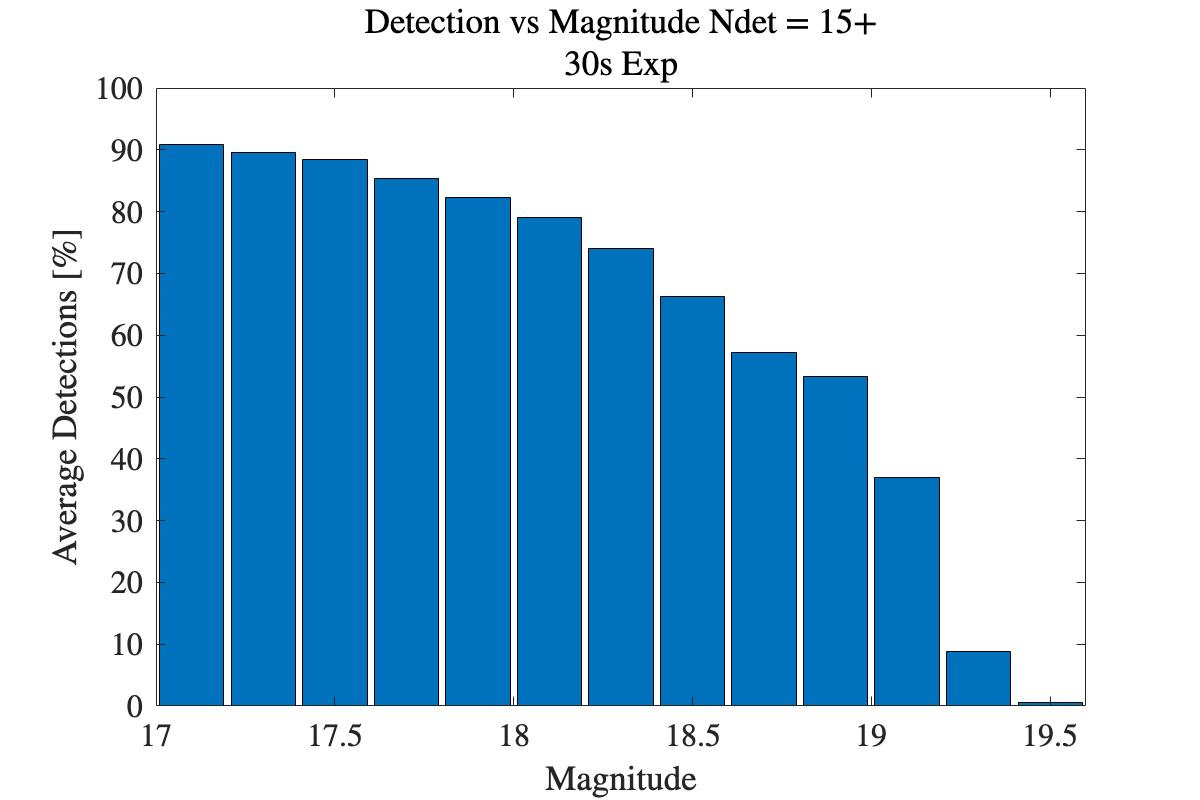




binEdges = linspace(17.0,20, 30);
binEfficiencies(1) = median(median(mB17_175))*100;
binEfficiencies(2) = median(median(mB175_18))*100;
binEfficiencies(3) = median(median(mB18_185))*100;
binEfficiencies(4) = median(median(mB185_19))*100;
binEfficiencies(5) = median(median(mB19_195,'omitnan'))*100;
binEfficiencies(6) = median(median(mB1195))*100;



binCenters =[17.25,17.75,18.25,18.75,19.25,19.75];

cbinE(1) = median(mean(cm17_172))*100;
cbinE(2) = median(mean(cm172_174))*100;
cbinE(3) = median(mean(cm174_176,'omitnan'))*100;
cbinE(4) = median(mean(cm176_178,'omitnan'))*100;
cbinE(5) = median(mean(cm178_18,'omitnan'))*100;
cbinE(6) = median(mean(cm18_182,'omitnan'))*100;
cbinE(7) = median(mean(cm182_184,'omitnan'))*100;
cbinE(8) = median(mean(cm184_186,'omitnan'))*100;
cbinE(9) = median(mean(cm186_188,'omitnan'))*100;
cbinE(10) = median(median(cm188_19,'omitnan'))*100;
cbinE(11) = median(median(cm19_192,'omitnan'))*100;
cbinE(12) = median(median(cm192_194,'omitnan'))*100;
cbinE(13) = median(median(cm194_196,'omitnan'))*100;





binCenters =[17.1,17.3,17.5,17.7,17.9,18.1,18.3,18.5,18.7,18.9,19.1,19.3,19.5];





% Plot the histogram
figure('Position', [100, 100, 600, 400]);
bar(binCenters, cbinE,"BarWidth",0.9,"BarLayout","stacked");
xlabel('Magnitude');
ylabel('Average Detections [%]');
title(sprintf('Detection vs Magnitude Ndet = 15+\n 30s Exp'));
xlim([17,19.6])


fprintf('All sources in all visits:')

All sources in all visits:

fprintf('%.2f%% out of %i sources survived ',median(median(allSrcStat))*100,sum(sum(allSrcN)))

69.80% out of 2429385 sources survived 


$$17<M<17\ldotp 5$$


fprintf('%.2f%% out of %i sources survived ',median(median(mB17_175))*100,sum(sum(nB17_175)))

90.15% out of 268900 sources survived 


$$17\ldotp 5<M<18$$


fprintf('%.2f%% out of %i sources survived ',median(median(mB175_18))*100,sum(sum(nB175_18)))

85.96% out of 310052 sources survived 


$$18<M<18\ldotp 5$$


fprintf('%.2f%% out of %i sources survived ',median(median(mB18_185))*100,sum(sum(nB18_185)))

77.94% out of 323561 sources survived 


$$18\ldotp 5<M<19$$


fprintf('%.2f%% out of %i sources survived ',median(median(mB185_19))*100,sum(sum(nB185_19)))

61.14% out of 324821 sources survived 


$$19<M<19\ldotp 5$$


fprintf('%.2f%% of %i sources survived ',median(median(mB19_195),'omitnan')*100,sum(sum(nB19_195)))

21.02% of 254321 sources survived 


$$19\ldotp 5<M$$


fprintf('%.2f%% of  %i sources survived ',median(median(mB1195),'omitnan')*100,sum(sum(nB1195)))

0.54% of  72621 sources survived 


%fprintf('9.97% of %i sources survived ',sum(sum(nB19_195)))

%fprintf('0% of  %i sources survived ',sum(sum(nB1195)))

## NAN FPR frequency VS mag

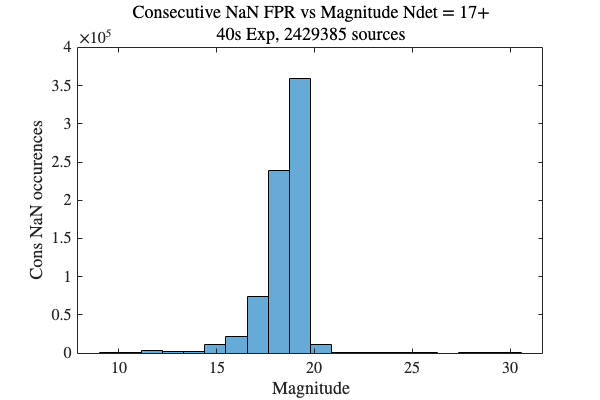

% Plot the histogram
V =AllFap;
figure('Position', [100, 100, 600, 400]);
histogram(V,20);
xlabel('Magnitude');
ylabel('Cons NaN occurences');
title(sprintf('Consecutive NaN FPR vs Magnitude Ndet = 17+\n 40s Exp, %i sources',AllS));

%xlim([12,20])
%ylim([0,0.0002])

### Detection  methods FPR

taking a visit from sunframe. applying detection method on all sources while scrambling the data

Where Method 1 is 2 consecutive deviating data points

method 2 is run mean filter with threshold = 5 and window = 2

method 3 is Area detrction

and "Method" 4 is the occurence of consecutive nans within the data.

FPv = [ mean(FRD1(:,4));mean(FRD2(:,4));mean(FRD2(:,4));mean(mean(Fap(:,3:end))) ]

Index in position 2 exceeds array bounds. Index must not exceed 1.

figure('Position', [100, 100, 600, 400]);
bar(FPv)
labels = {'2 cons pts', 'RunMeanFilter', 'AreaDetection', '2 cons NaN', 'Elderberry'};
xticks(1:length(FPv));


xticklabels(labels);
xtickangle(45); 
ylabel('Detection rate')
title('FP rates; 40s')
